## Lab 4.2

(a)

题目要求：

求x(t)的CTFT解析表达式。

分析：

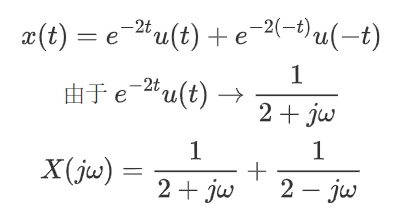

结论：

(b)

题目要求：

创建 y(t) = x(t - 5) 在区间t上的样本，并解析出信号y(t)的CTFT。

分析：

clear;
tau = 0.01;
T = 10;
N = T / tau;

t = linspace(0, T - tau, N);
y = exp(-2 * abs(t - 5));

由解析得：

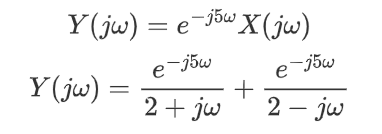

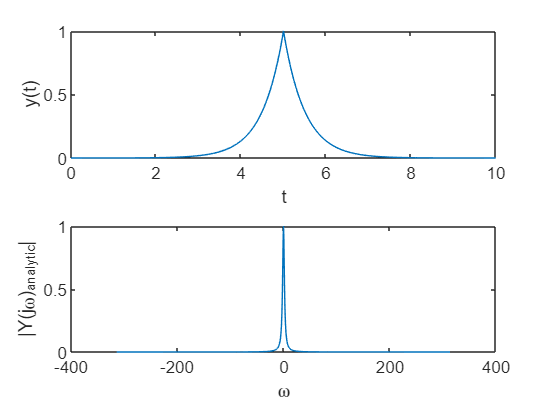

w = -(pi / tau) + (0 : N - 1) * (2 * pi / T);

% 分析得出Y
Y_a = exp(-5j * w) ./ (2 + 1j * w) + exp(-5j * w) ./ (2 - 1j * w);
Y_m = abs(Y_a);

%绘图
figure
subplot(2,1,1),plot(t,y),xlabel('t'),ylabel('y(t)');
subplot(2,1,2),plot(w,Y_m),xlabel('\omega'),ylabel('|Y(j\omega)_{analytic}|');

结论：如答图，解析得出的y(t)如图。

(c)

题目要求：

计算样本 Y(jw_k)。

分析：

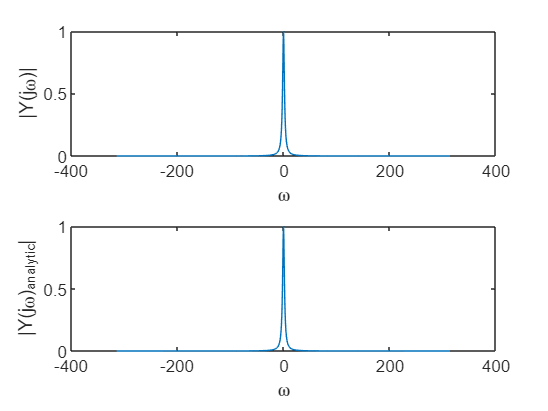

% 计算得出Y
Y = fftshift(tau * fft(y));
Ym = abs(Y);

%绘图
figure
subplot(2,1,1),plot(w,Ym),xlabel('\omega'),ylabel('|Y(j\omega)|');
subplot(2,1,2),plot(w,Y_m),xlabel('\omega'),ylabel('|Y(j\omega)_{analytic}|');

结论：如答图。

(d)

题目要求：

构造一个频率样本w。

分析：

在上述题目中已按照此方法构造。

>> w = -(pi / tau) + (0 : N - 1) * (2 * pi / T)；

(e)

题目要求：

利用w向量直接由Y计算出X(jw)，并存入向量中。

分析：

y(t)是通过时移与x(t)相联系的，因此

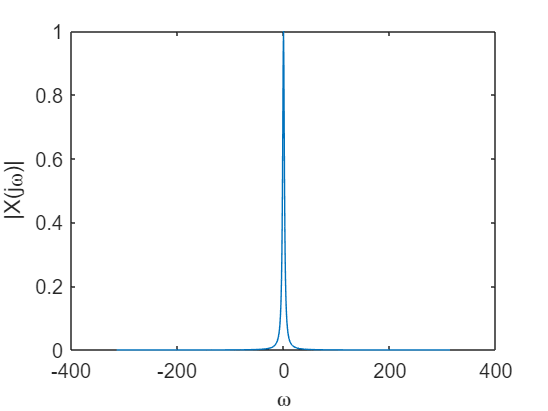

X = Y .* exp(1j * 5 .* w);

% 绘图
figure
plot(w,abs(X)),xlabel('\omega'),ylabel('|X(j\omega)|');

结论：如答图。

(f)

题目要求：

利用abs与angle函数画出w标定频率范围内的X的幅值与相位，同时画出解析得出的X的幅值与相位。这两者相符吗？

分析：

由上述分析得出的X(jw)为

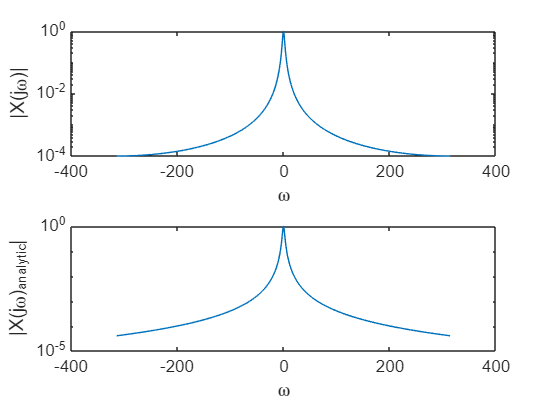

X_a = 1 ./ (2 + 1j * w) + 1 ./ (2 - 1j * w);

figure
subplot(2,1,1),semilogy(w,abs(X)),xlabel('\omega'),ylabel('|X(j\omega)|');
subplot(2,1,2),semilogy(w,abs(X_a)),xlabel('\omega'),ylabel('|X(j\omega)_{analytic}|');

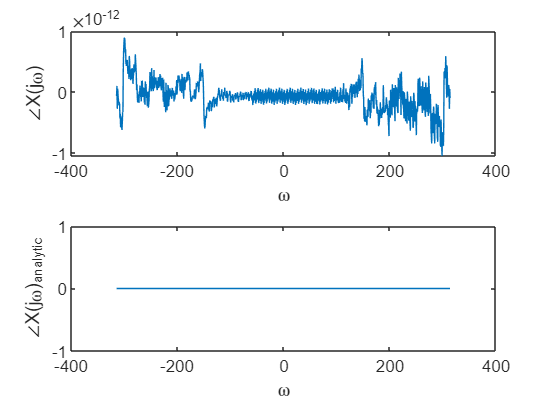


figure
subplot(2,1,1),plot(w,angle(X)),xlabel('\omega'),ylabel('∠X(j\omega)');
subplot(2,1,2),plot(w,angle(X_a)),xlabel('\omega'),ylabel('∠X(j\omega)_{analytic}');

结论：如答图，在较高的频率上相似度不如在较低频率上好，因为用n * tau近似t，则在tau长度内，信号变化不大的频率分量近似程度会更好。

(g)

题目要求：

利用abs与angle函数绘制Y的幅值和相位，与X比较。

分析：

可知，二者的幅值应相同，但相角应有明显差别。

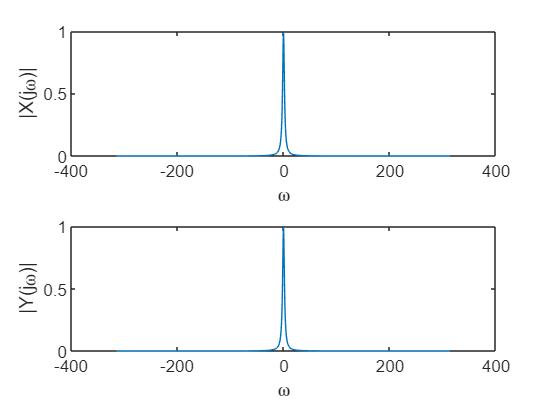

figure
subplot(2,1,1),plot(w,abs(X)),xlabel('\omega'),ylabel('|X(j\omega)|');
subplot(2,1,2),plot(w,abs(Y)),xlabel('\omega'),ylabel('|Y(j\omega)|');

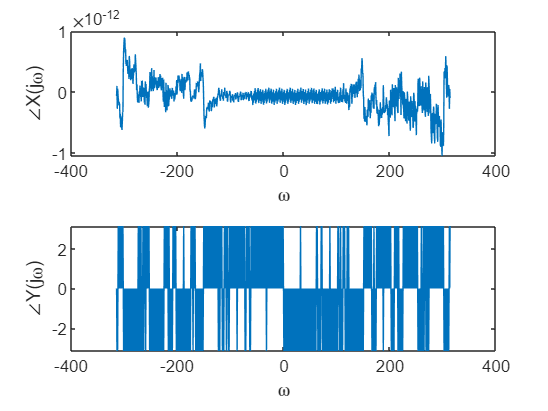


figure
subplot(2,1,1),plot(w,angle(X)),xlabel('\omega'),ylabel('∠X(j\omega)');
subplot(2,1,2),plot(w,angle(Y)),xlabel('\omega'),ylabel('∠Y(j\omega)');

结论：

如答图，X与Y幅值相同，但相位有较大差别，这是因为在时域上发生的时移在频域上体现为相角的改变。